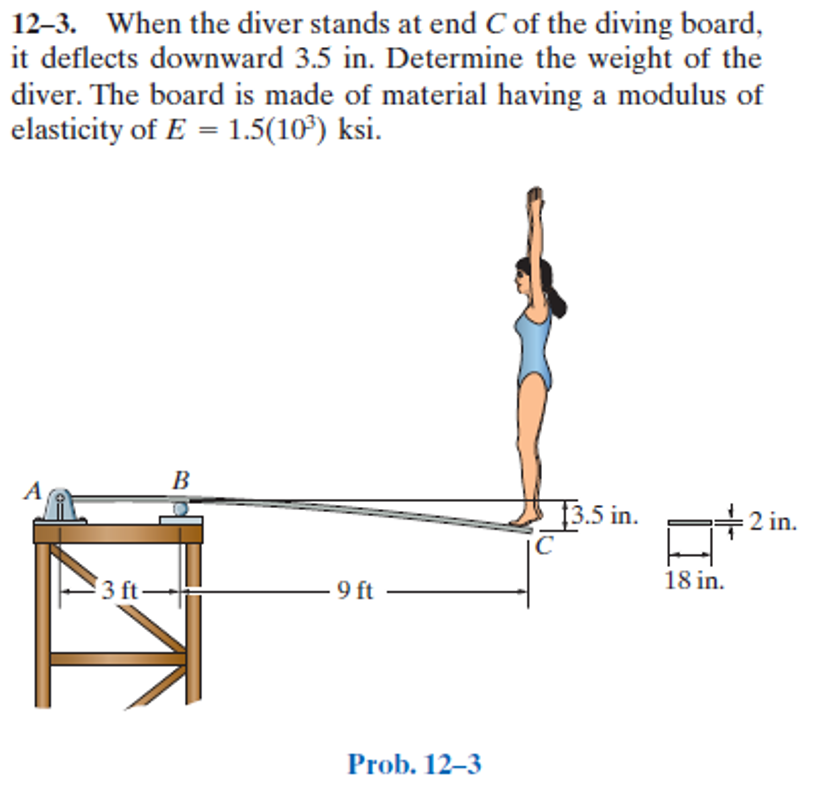

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# load data

W = sym('W');

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('reaction', 'force', 'Rb', 3*u.ft);
b = b.add('concentrated', 'force', -W, 12*u.ft);
b.L = 12*u.ft;

# section properties

b.E = rewrite(1.5e3*u.ksi, [u.lbf u.ft]);
b.I = rewrite(18*2^3/12*u.in^4, u.ft);

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('factor');
b.E = rewrite(b.E, u.ksi);
b.I = rewrite(b.I, u.in);

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{W\,x\,\left(x-3\,\mathrm{ft}\right)\,\left(x+3\,\mathrm{ft}\right)}{250000}\,\frac{1}{{\mathrm{ft}}^{2}\,\mathrm{lbf}} & \text{ if }x\leq 3\,\mathrm{ft}\\ \frac{W\,\left(x-3\,\mathrm{ft}\right)\,\left(x^{2}-33\,x\,\mathrm{ft}+36\,{\mathrm{ft}}^{2}\right)}{750000}\,\frac{1}{{\mathrm{ft}}^{2}\,\mathrm{lbf}} & \text{ if }3\,\mathrm{ft}<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} \frac{3\,W\,\left(3\,{\mathrm{ft}}^{2}-x^{2}\right)}{250000}\,\frac{1}{{\mathrm{ft}}^{2}\,\mathrm{lbf}} & \text{ if }x\leq 3\,\mathrm{ft}\\ \frac{W\,\left(x^{2}-24\,x\,\mathrm{ft}+45\,{\mathrm{ft}}^{2}\right)}{250000}\,\frac{1}{{\mathrm{ft}}^{2}\,\mathrm{lbf}} & \text{ if }3\,\mathrm{ft}<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} -3\,W\,x & \text{ if }x\leq 3\,\mathrm{ft}\\ W\,\left(x-12\,\mathrm{ft}\right) & \text{ if }3\,\mathrm{ft}<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} -3\,W & \text{ if }x\leq 3\,\mathrm{ft}\\ W & \text{ if }3\,\mathrm{ft}<x \end{array}\right.$$

w

$$w(x) = 0$$

# reactions and hinges

ra 

$$ra = \left(\begin{array}{cc} \mathrm{Ra} & -3\,W\\ \mathrm{Rb} & 4\,W \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

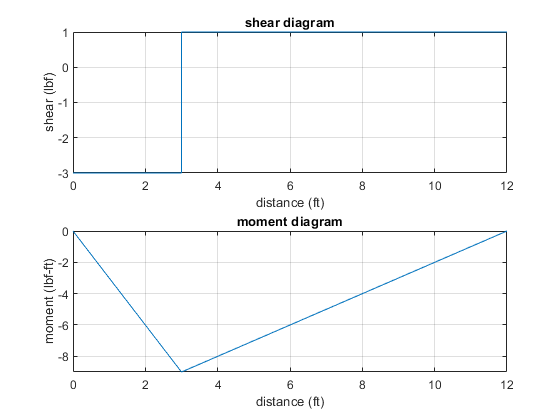

beam.shear_moment(m, v, [0 b.L], W, 1, {'lbf' 'ft'});

# weight of diver

Wsol = solve(y(b.L) == rewrite(-3.5*u.in, u.ft));
Wsol_vpa = vpa(Wsol, 5) %#ok<NASGU> 

$$Wsol\_vpa = 112.53\,\mathrm{lbf}$$

# clean up

addvar(y);
setassum(old_assum, 'clear');
clear Wsol_vpa;
clear old_assum;